%==========================================================================
% Author:    Naghmeh Akhavan, PhD (N. Akhavan)
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Purpose:
%   Compare REMpost bout duration versus REM propensity across Mouse, Rat,
%   and Human using a consistent analysis pipeline, and summarize the
%   relationship with:
%     (i) scatter + linear regression in the "increasing zone", and
%     (ii) binned mean REMpost vs propensity WITH ERROR BARS.
%
% Core pipeline (consistent across species):
%   1) Long-wake DROP (LW >= WAKE_BREAK_MIN minutes):
%        - Rodents: prefer MaxWake* (max contiguous Wake block); 
%   2) Bin cycles by REMpre (fixed edges in seconds).
%   3) In each REMpre bin: fit a 2-component GMM to z = log(NREM) (seconds).
%   4) Convert GMM -> CDF F(t) and compute propensity:
%          p(t) = [F(t+Δ) − F(t)] / [1 − F(t)],  Δ = DELTA_SEC.
%   5) Increasing zone per bin: global minimum of p(t) then first local maximum after it.
%   6) Pool cycles whose NREM is within [t_min, t_peak]; store:
%          x = p(NREM),   y = REMpost.
%   7) Plot:
%        - Scatter(x,y) + fitted regression line
%        - Bar plot of mean(y) in propensity bins with error bars (SEM or SD)
%
% Error bars (new in this version):
%   - ERR_TYPE = "SEM" (default) uses sd/sqrt(n)
%   - ERR_TYPE = "SD" uses sample SD
%   - Error bars are shown only if bin count >= MIN_N_ERR (default 3)
%
% Inputs:
%   Rodents (CSV): BigResultTable_mouse_* and BigResultTable_rat_*
%   Human (MAT):   Combined_BigResultTable.mat and Combined_BigStageDetailsTable.mat
%
% Outputs:
%   - For each dataset: console summary + scatter/regression figure + bar+errorbar figure
%
% Last updated: 2026-01-19
%==========================================================================
clear; clc;


## Colors

colMouse = [0.55 0.27 0.68];
colRat   = [0.90 0.50 0.10];
colHuman = [0.20 0.70 0.50];


## Long-wake threshold

WAKE_BREAK_MIN = 2;
WAKE_BREAK_SEC = WAKE_BREAK_MIN*60;


## Paths

mouseLightCSV = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light.csv";
mouseDarkCSV  = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark.csv";
ratLightCSV   = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light.csv";
ratDarkCSV    = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark.csv";

baseFolder = 'C:\Users\naghm\OneDrive\Desktop\combined_out';
matR = fullfile(baseFolder, 'Combined_BigResultTable.mat');
matD = fullfile(baseFolder, 'Combined_BigStageDetailsTable.mat');

datasets = { ...
    struct('name','Mouse Light','type','csv','path',mouseLightCSV, 'col',colMouse) ...
  , struct('name','Mouse Dark' ,'type','csv','path',mouseDarkCSV , 'col',colMouse) ...
  , struct('name','Rat Light'  ,'type','csv','path',ratLightCSV  , 'col',colRat  ) ...
  , struct('name','Rat Dark'   ,'type','csv','path',ratDarkCSV   , 'col',colRat  ) ...
  , struct('name','Human'      ,'type','human','pathR',matR,'pathD',matD,'col',colHuman) ...
};


## Settings

REMpreBinEdges = [0 30 60 90 120 150 Inf];  % seconds
DELTA_SEC      = 30;                        % propensity horizon (Δt) in seconds
MIN_POINTS_BIN = 25;                        % minimum points to fit GMM per bin
N_BINS_BAR     = 9;                         % bar plot bins

% ---- Error-bar settings (NEW) ----
ERR_TYPE   = "SEM";  % "SEM" (default) or "SD"
MIN_N_ERR  = 3;      % require >= MIN_N_ERR points to display an errorbar



## Run all datasets

% for each dataset: load + normalize + long wake filter
for d = 1:numel(datasets)
    tag = datasets{d}.name;
    COL = datasets{d}.col;

    fprintf('\n================== %s ==================\n', tag);

    % Load + filter
    if datasets{d}.type == "csv"
        assert(isfile(datasets{d}.path), 'Missing CSV: %s', datasets{d}.path);
        T = readtable(datasets{d}.path, 'TextType','string');
        T = normalize_cycle_table(T);

        [Tkeep, kept, dropped, filterMsg] = apply_longwake_filter_generic(T, WAKE_BREAK_SEC);
        fprintf('Kept=%d, Dropped=%d  [%s; threshold=%g min]\n', kept, dropped, filterMsg, WAKE_BREAK_MIN);

    else
        % Human: load Combined_BigResultTable + StageDetails and filter
        assert(isfile(datasets{d}.pathR), 'Missing %s.', datasets{d}.pathR);
        S1 = load(datasets{d}.pathR);
        assert(isfield(S1,'Combined_BigResultTable'), 'MAT missing Combined_BigResultTable');
        R = S1.Combined_BigResultTable;
        R = normalize_cycle_table(R);

        if isfile(datasets{d}.pathD)
            S2 = load(datasets{d}.pathD);
            assert(isfield(S2,'Combined_BigStageDetailsTable'), 'MAT missing Combined_BigStageDetailsTable');
            D = S2.Combined_BigStageDetailsTable;
            D.REM_Cycle_Index = string(D.REM_Cycle_Index);
            D.Stage    = double(D.Stage);
            D.Duration = double(D.Duration);

            % prefer StageDetails long-wake
            [Rkeep, kept, dropped, filterMsg] = apply_longwake_filter_human_stageDetails(R, D, WAKE_BREAK_SEC);
            fprintf('Human long-wake DROP: dropped %d cycles; kept %d. [%s]\n', dropped, kept, filterMsg);
        else
            % sanity check: fallback to generic
            [Rkeep, kept, dropped, filterMsg] = apply_longwake_filter_generic(R, WAKE_BREAK_SEC);
            fprintf('Human long-wake DROP: dropped %d cycles; kept %d. [%s]\n', dropped, kept, filterMsg);
        end

        Tkeep = Rkeep;
    end

    % Pull numeric arrays
    NREM    = double(Tkeep.NREM(:));
    REMpre  = double(Tkeep.REMpre(:));
    REMpost = double(Tkeep.REMpost(:));
    % define valid rows
    valid_all = isfinite(NREM) & (NREM > 0) & isfinite(REMpre);
    valid_xy  = valid_all & isfinite(REMpost) & (REMpost > 0);

    fprintf('%s: Rows=%d | Valid for bin/GMM=%d | Valid for corr=%d\n', ...
        tag, height(Tkeep), nnz(valid_all), nnz(valid_xy));

    % Bin by REMpre
    bFull = discretize(REMpre, REMpreBinEdges);  % 1..6 or NaN
    number_bins = numel(REMpreBinEdges);

    % pooled increasing-zone data
    xProp_inc = [];
    yREMpost  = [];

    % -------- Loop bins --------
    for bin_number = 1:number_bins-1
        binMask_fit = valid_all & (bFull == bin_number);
        n_fit = nnz(binMask_fit);

        if n_fit == 0
            fprintf('  Bin %d [%g,%g): n_fit=0 (skip)\n', bin_number, REMpreBinEdges(bin_number), REMpreBinEdges(bin_number+1));
            continue;
        end

        fprintf('  Bin %d [%g,%g): n_fit=%d\n', bin_number, REMpreBinEdges(bin_number), REMpreBinEdges(bin_number+1), n_fit);

        NREM_subset = NREM(binMask_fit);
        z = log(NREM_subset(:));
        z = z(isfinite(z));

        if numel(z) < MIN_POINTS_BIN
            fprintf('    too few points for GMM (n=%d < %d); skip\n', numel(z), MIN_POINTS_BIN);
            continue;
        end

        % Fit 2-comp GMM on log(NREM)
        [w, mu, sd] = fit_gmm_1d(z, 2, struct('nStarts',20,'maxIter',250,'tol',1e-6, ...
                                              'trimFrac',0.01,'sdMin',0.08,'sdMax',3.0, ...
                                              'clipQuantiles',[0.5 99.5]));
        % order by mean
        [mu, ord] = sort(mu); sd = sd(ord); w = w(ord);
        mu_s = mu(1); std_s = sd(1);
        mu_l = mu(2); std_l = sd(2);
        k_l  = w(2);

        Phi = @(u) 0.5*(1+erf(u./sqrt(2)));
        cdf_fun = @(t) (1 - k_l).*Phi((log(max(t,eps)) - mu_s)./std_s) + ...
                            k_l .*Phi((log(max(t,eps)) - mu_l)./std_l);
        propensity_fun = @(t) (cdf_fun(t + DELTA_SEC) - cdf_fun(t)) ./ max(1 - cdf_fun(t), eps);

        % Data-adaptive grid for propensity curve
        tmax = ceil(prctile(NREM_subset, 99.5));
        tmax = max(tmax, 300);              % avoid too small
        tvec = 1:tmax;

        prop_vals = arrayfun(propensity_fun, tvec);

        % Robust "increasing zone": global min then FIRST local max after min ---
        [~, i_min] = min(prop_vals);

        locmax = find(islocalmax(prop_vals));
        locmax = locmax(locmax > i_min);

        if isempty(locmax)
            % fallback
            [~, i_max_after] = max(prop_vals(i_min:end));
            i_peak = i_min + i_max_after - 1;
        else
            i_peak = locmax(1);  % FIRST local max after min
        end

        t_min  = tvec(i_min);
        t_peak = tvec(i_peak);

        fprintf('    increasing-zone: t_min=%d s, t_peak=%d s\n', t_min, t_peak);

        % Collect points in increasing zone 
        binMask_xy = valid_xy & (bFull == bin_number);
        idx = find(binMask_xy);
        for ii = 1:numel(idx)
            kkk = idx(ii);
            thisN = NREM(kkk);
            if thisN >= t_min && thisN <= t_peak
                xProp_inc = [xProp_inc; propensity_fun(thisN)];
                yREMpost  = [yREMpost;  REMpost(kkk)];
            end
        end
    end

    % -------- Report sizes --------
    fprintf('  %s: Increasing-zone pooled n=%d\n', tag, numel(xProp_inc));

    % Diagnostic: check if propensity is nearly constant (causes r=NaN)
    if ~isempty(xProp_inc)
        fprintf('  %s propensity: min=%.6f max=%.6f std=%.6g\n', tag, min(xProp_inc), max(xProp_inc), std(xProp_inc));
    end

    % Scatter + fit
    if numel(xProp_inc) >= 3
        [r_inc, p_inc] = corr_pearson_nontb(xProp_inc, yREMpost);

        A = [ones(numel(xProp_inc),1), xProp_inc];
        b = A \ yREMpost;
        b0 = b(1); b1 = b(2);

        fprintf('  %s inc-zone: r=%.3f, p=%.3g, slope=%.4g\n', tag, r_inc, p_inc, b1);

        figure('Color','w');
        scatter(xProp_inc, yREMpost, 22, 'filled', ...
            'MarkerFaceColor',COL, 'MarkerEdgeColor',COL, ...
            'MarkerFaceAlpha',0.30, 'MarkerEdgeAlpha',0.25);
        hold on;
        xx = linspace(min(xProp_inc), max(xProp_inc), 200);
        yy = b0 + b1*xx;
        plot(xx, yy, '-', 'Color',COL, 'LineWidth', 2);
        hold off;

        xlabel('Propensity at REM_{post} onset');
        ylabel('|REM_{post}| (s)');
        set(gca,'FontSize',18);
        title(sprintf('%s — Increasing zone: n=%d, r=%.2f, p=%.3g (LW \\ge %g min)', ...
            tag, numel(xProp_inc), r_inc, p_inc, WAKE_BREAK_MIN));

    else
        warning('%s: Not enough increasing-zone points for regression.', tag);
    end


## Bar plot: binned means + error bars


================== Mouse Light ==================


Kept=4017, Dropped=1283  [Wake fallback (total Wake) >= 120s; threshold=2 min]


Mouse Light: Rows=4017 | Valid for bin/GMM=4005 | Valid for corr=3941


  Bin 1 [0,30): n_fit=1764


    increasing-zone: t_min=1 s, t_peak=65 s


  Bin 2 [30,60): n_fit=955


    increasing-zone: t_min=1 s, t_peak=28 s


  Bin 3 [60,90): n_fit=538


    increasing-zone: t_min=136 s, t_peak=889 s


  Bin 4 [90,120): n_fit=359


    increasing-zone: t_min=152 s, t_peak=1075 s


  Bin 5 [120,150): n_fit=214


    increasing-zone: t_min=163 s, t_peak=1207 s


  Bin 6 [150,Inf): n_fit=175


    increasing-zone: t_min=1 s, t_peak=1375 s


  Mouse Light: Increasing-zone pooled n=1389


  Mouse Light propensity: min=0.003945 max=0.294366 std=0.0500539


  Mouse Light inc-zone: r=0.158, p=3.3e-09, slope=154.1


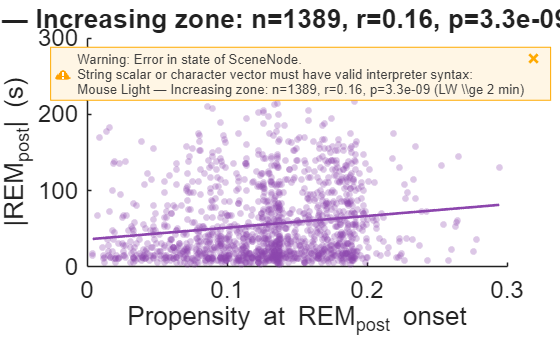

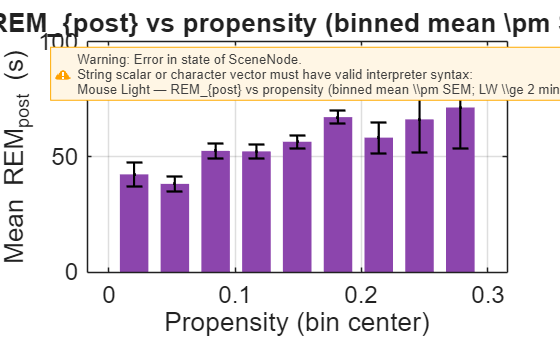

  Mouse Light bar bins: n per bin = [69 113 217 292 316 321 42 12 7 ]



================== Mouse Dark ==================


Kept=743, Dropped=564  [Wake fallback (total Wake) >= 120s; threshold=2 min]


Mouse Dark: Rows=743 | Valid for bin/GMM=739 | Valid for corr=722


  Bin 1 [0,30): n_fit=263


    increasing-zone: t_min=1 s, t_peak=438 s


  Bin 2 [30,60): n_fit=190


    increasing-zone: t_min=81 s, t_peak=553 s


  Bin 3 [60,90): n_fit=126


    increasing-zone: t_min=110 s, t_peak=890 s


  Bin 4 [90,120): n_fit=90


    increasing-zone: t_min=1 s, t_peak=1005 s


  Bin 5 [120,150): n_fit=47


    increasing-zone: t_min=1 s, t_peak=113 s


  Bin 6 [150,Inf): n_fit=23


    too few points for GMM (n=23 < 25); skip


  Mouse Dark: Increasing-zone pooled n=583


  Mouse Dark propensity: min=0.004848 max=0.331515 std=0.0558352


  Mouse Dark inc-zone: r=-0.016, p=0.695, slope=-13.26


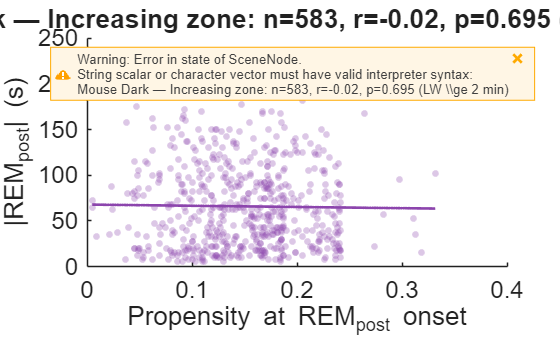

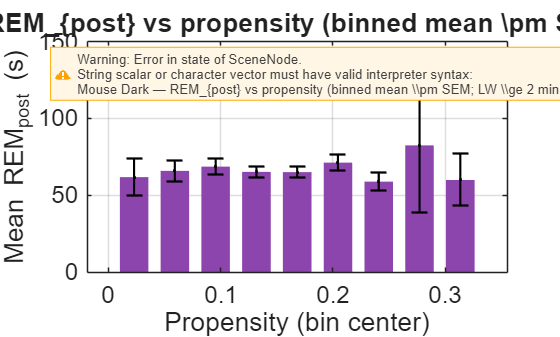

  Mouse Dark bar bins: n per bin = [11 47 99 132 154 75 57 3 5 ]



================== Rat Light ==================


Kept=2092, Dropped=674  [Wake fallback (total Wake) >= 120s; threshold=2 min]


Rat Light: Rows=2092 | Valid for bin/GMM=2089 | Valid for corr=2087


  Bin 1 [0,30): n_fit=1218


    increasing-zone: t_min=709 s, t_peak=709 s


  Bin 2 [30,60): n_fit=217


    increasing-zone: t_min=99 s, t_peak=487 s


  Bin 3 [60,90): n_fit=152


    increasing-zone: t_min=52 s, t_peak=298 s


  Bin 4 [90,120): n_fit=129


    increasing-zone: t_min=203 s, t_peak=466 s


  Bin 5 [120,150): n_fit=171


    increasing-zone: t_min=94 s, t_peak=603 s


  Bin 6 [150,Inf): n_fit=202


    increasing-zone: t_min=90 s, t_peak=712 s


  Rat Light: Increasing-zone pooled n=430


  Rat Light propensity: min=0.022584 max=0.239895 std=0.0394007


  Rat Light inc-zone: r=0.124, p=0.0101, slope=226.4


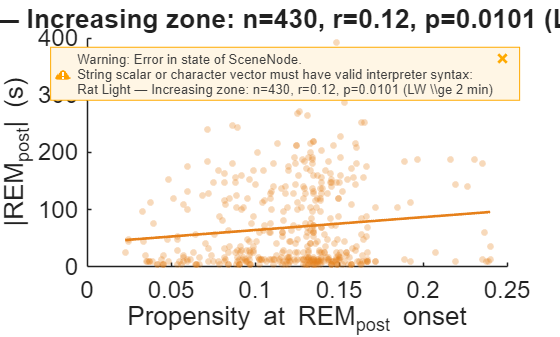

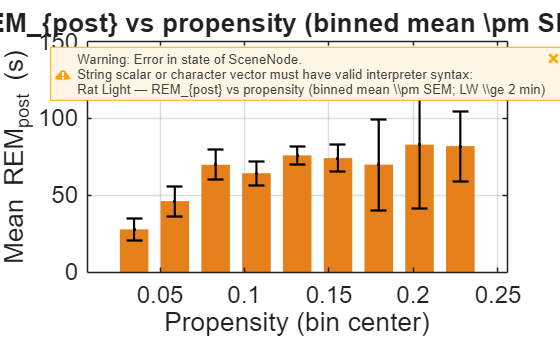

  Rat Light bar bins: n per bin = [20 29 55 72 142 90 6 4 12 ]



================== Rat Dark ==================


Kept=1747, Dropped=565  [Wake fallback (total Wake) >= 120s; threshold=2 min]


Rat Dark: Rows=1747 | Valid for bin/GMM=1745 | Valid for corr=1743


  Bin 1 [0,30): n_fit=1012


    increasing-zone: t_min=710 s, t_peak=710 s


  Bin 2 [30,60): n_fit=162


    increasing-zone: t_min=104 s, t_peak=521 s


  Bin 3 [60,90): n_fit=140


    increasing-zone: t_min=49 s, t_peak=337 s


  Bin 4 [90,120): n_fit=115


    increasing-zone: t_min=68 s, t_peak=362 s


  Bin 5 [120,150): n_fit=147


    increasing-zone: t_min=75 s, t_peak=515 s


  Bin 6 [150,Inf): n_fit=169


    increasing-zone: t_min=87 s, t_peak=680 s


  Rat Dark: Increasing-zone pooled n=373


  Rat Dark propensity: min=0.024684 max=0.160484 std=0.0312824


  Rat Dark inc-zone: r=0.117, p=0.0234, slope=265.3


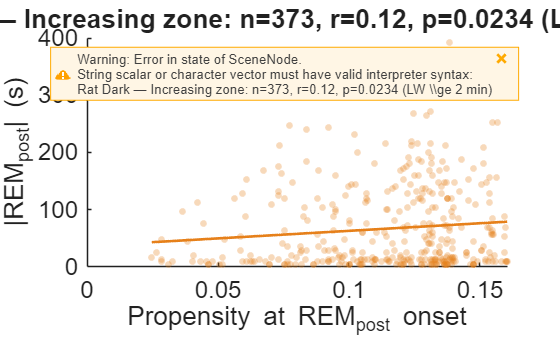

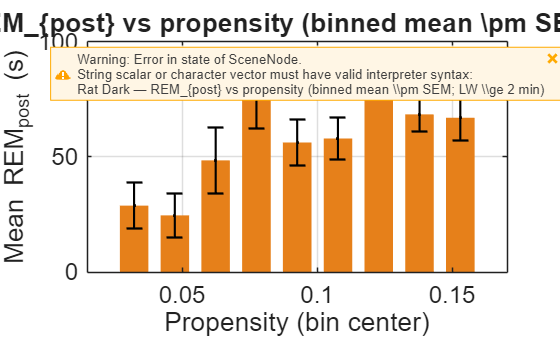

  Rat Dark bar bins: n per bin = [9 13 17 33 35 48 69 99 50 ]



================== Human ==================


Human long-wake DROP: dropped 1028 cycles; kept 3994. [StageDetails: any Stage==5 block >= 120s]


Human: Rows=3994 | Valid for bin/GMM=3397 | Valid for corr=3202


  Bin 1 [0,30): n_fit=0 (skip)


  Bin 2 [30,60): n_fit=343


    increasing-zone: t_min=6418 s, t_peak=6418 s


  Bin 3 [60,90): n_fit=271


    increasing-zone: t_min=5765 s, t_peak=5765 s


  Bin 4 [90,120): n_fit=230


    increasing-zone: t_min=5166 s, t_peak=5166 s


  Bin 5 [120,150): n_fit=204


    increasing-zone: t_min=11464 s, t_peak=11464 s


  Bin 6 [150,Inf): n_fit=2349


    increasing-zone: t_min=1556 s, t_peak=7666 s


  Human: Increasing-zone pooled n=678


  Human propensity: min=0.000491 max=0.035360 std=0.00817715


  Human inc-zone: r=0.161, p=2.41e-05, slope=1.369e+04


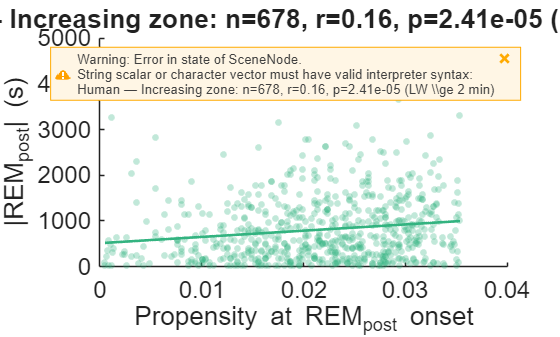

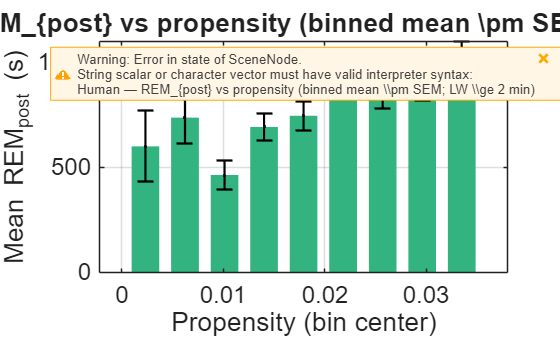

  Human bar bins: n per bin = [24 26 41 84 89 113 114 123 64 ]



    if numel(xProp_inc) >= 4
        prop_min = min(xProp_inc);
        prop_max = max(xProp_inc);
        edges   = linspace(prop_min - 1e-4, prop_max + 1e-4, N_BINS_BAR+1);
        centers = 0.5*(edges(1:end-1)+edges(2:end));

        bin_id = discretize(xProp_inc, edges);

        bin_means = nan(N_BINS_BAR,1);
        bin_sd    = nan(N_BINS_BAR,1);
        bin_sem   = nan(N_BINS_BAR,1);
        bin_n     = zeros(N_BINS_BAR,1);

        for bi = 1:N_BINS_BAR
            yy = yREMpost(bin_id==bi);
            yy = yy(isfinite(yy));
            bin_n(bi) = numel(yy);

            if bin_n(bi) >= 2
                bin_means(bi) = mean(yy);
                bin_sd(bi)    = std(yy, 0);            % sample SD
                bin_sem(bi)   = bin_sd(bi) / sqrt(bin_n(bi));
            elseif bin_n(bi) == 1
                bin_means(bi) = yy;                    % single point
                bin_sd(bi)    = NaN;
                bin_sem(bi)   = NaN;
            end
        end

        % SEM or SD
        if ERR_TYPE == "SD"
            err = bin_sd;
        else
            err = bin_sem;
        end

        % suppress error bars for tiny bins, but keep bar height
        err(bin_n < MIN_N_ERR) = NaN;

        figure('Color','w');
        bar(centers, bin_means, 'BarWidth',0.7, 'FaceColor',COL, 'EdgeColor','none');
        hold on;
        errorbar(centers, bin_means, err, 'k.', 'LineWidth',1.6, 'CapSize',12);
        hold off;

        grid on; box on;
        xlabel('Propensity (bin center)');
        ylabel('Mean REM_{post} (s)');
        title(sprintf('%s — REM_{post} vs propensity (binned mean \\pm %s; LW \\ge %g min)', ...
            tag, ERR_TYPE, WAKE_BREAK_MIN));
        set(gca,'FontSize',18);

        % optional: print bin counts (helps interpret error bars)
        fprintf('  %s bar bins: n per bin = [%s]\n', tag, sprintf('%d ', bin_n));
    end
end

## Functions



function T = normalize_cycle_table(T)
    % Ensure required columns and types.
    vn = string(T.Properties.VariableNames);

    if ~ismember("Subject_Index", vn), T.Subject_Index = strings(height(T),1); end
    if ~ismember("REM_Cycle_Index", vn), T.REM_Cycle_Index = strings(height(T),1); end

    T.Subject_Index   = string(T.Subject_Index);
    T.REM_Cycle_Index = string(T.REM_Cycle_Index);

    need = ["NREM","Wake","Movement","IREM","REMpre","REMpost"];
    for v = need
        if ~ismember(v, vn), T.(v) = NaN(height(T),1); end
        T.(v) = double(T.(v));
    end
    if (all(isnan(T.IREM)) || ~ismember("IREM", vn)) && all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
        T.IREM = T.NREM + T.Wake + T.Movement;
    end
end

function [Tkeep, kept, dropped, msg] = apply_longwake_filter_generic(T, WAKE_BREAK_SEC)
    vn = string(T.Properties.VariableNames);

    maxWakeCandidates = ["MaxWakeSec","MaxWake_s","MaxWakeInIREMSec","MaxWakeInIREM_s","MaxWakeBlockSec","MaxWakeBlock_s"];
    if any(ismember(maxWakeCandidates, vn))
        cname = maxWakeCandidates(find(ismember(maxWakeCandidates, vn), 1, 'first'));
        maxWakeSec = double(T.(cname));
        dropFlag = isfinite(maxWakeSec) & (maxWakeSec >= WAKE_BREAK_SEC);
        msg = sprintf("max Wake block '%s' >= %gs", cname, WAKE_BREAK_SEC);

    elseif ismember("Wake", vn)
        % Fallback: total Wake within IREM
        dropFlag = isfinite(T.Wake) & (double(T.Wake) >= WAKE_BREAK_SEC);
        msg = sprintf("Wake fallback (total Wake) >= %gs", WAKE_BREAK_SEC);

    else
        dropFlag = false(height(T),1);
        msg = "no MaxWake* and no Wake column — no LW filtering applied";
    end

    Tkeep = T(~dropFlag,:);
    kept = height(Tkeep);
    dropped = sum(dropFlag);
end

function [Rkeep, kept, dropped, msg] = apply_longwake_filter_human_stageDetails(R, D, WAKE_BREAK_SEC)
    % Drop cycles if any Wake block (Stage==5) duration >= threshold (seconds).
    % This is the most faithful "block" definition for human.
    msg = sprintf("StageDetails: any Stage==5 block >= %gs", WAKE_BREAK_SEC);

    D.ord = (1:height(D))';
    D = sortrows(D, {'REM_Cycle_Index','ord'});

    [G, keys] = findgroups(D.REM_Cycle_Index);
    hasLongWake = false(numel(keys),1);
    for gi = 1:numel(keys)
        idx = find(G==gi);
        st = D.Stage(idx);
        du = D.Duration(idx);
        if any(st==5 & du>=WAKE_BREAK_SEC)
            hasLongWake(gi) = true;
        end
    end

    Flag = table(keys, hasLongWake, 'VariableNames',{'REM_Cycle_Index','HasLongWake'});
    R2 = outerjoin(R, Flag, 'Keys','REM_Cycle_Index', 'MergeKeys',true, 'Type','left');
    dropFlag = (R2.HasLongWake==1);
    dropFlag(ismissing(R2.HasLongWake)) = false;

    Rkeep = R2(~dropFlag,:);
    kept = height(Rkeep);
    dropped = sum(dropFlag);
end

function [r, p] = corr_pearson_nontb(x, y)
    Phi = @(u) 0.5*(1+erf(u./sqrt(2)));
    x = x(:); y = y(:);
    m = isfinite(x) & isfinite(y);
    x = double(x(m));  y = double(y(m));
    n = numel(x);
    if n < 3 || all(x==x(1)) || all(y==y(1)), r = NaN; p = NaN; return; end
    x = x - mean(x); y = y - mean(y);
    r = (x'*y) / sqrt((x'*x) * (y'*y));
    r = max(min(r, 1-1e-12), -1+1e-12);
    z  = 0.5*log((1+r)/(1-r));
    se = 1/sqrt(n-3);
    p  = 2*(1 - Phi(abs(z)/se));
end

function q = quantile_nontb(x, p)
    x = sort(x(:)); n = numel(x); q = zeros(size(p));
    for k = 1:numel(p)
        if n==1, q(k)=x; continue; end
        idx = (n-1)*p(k) + 1;
        i0 = floor(idx); i1 = ceil(idx);
        if i0==i1
            q(k) = x(i0);
        else
            w = idx - i0;
            q(k) = (1-w)*x(i0) + w*x(i1);
        end
    end
end

function [w, mu, sd, info] = fit_gmm_1d(x, K, opts)
    x = x(:); x = x(isfinite(x));
    if nargin < 3, opts = struct; end
    g = @(f,def) (isfield(opts,f)&&~isempty(opts.(f))).*opts.(f) + ...
                 (~isfield(opts,f)||isempty(opts.(f))).*def;
    nStarts  = g('nStarts',30);
    maxIter  = g('maxIter',200);
    tol      = g('tol',1e-6);
    trimFrac = g('trimFrac',0.01);
    sdMin    = g('sdMin',0.08);
    sdMax    = g('sdMax',3.0);
    cq       = g('clipQuantiles',[0.5 99.5]);

    if ~isempty(cq)
        qlo = quantile_nontb(x, cq(1)/100);
        qhi = quantile_nontb(x, cq(2)/100);
        x   = x(x>=qlo & x<=qhi);
    end
    log2pi = log(2*pi);

    bestLL = -inf; best = [];
    for s = 1:nStarts
        q20 = quantile_nontb(x, 0.20);
        q80 = quantile_nontb(x, 0.80);
        mu0 = linspace(q20, q80, K) + 0.05*randn(1,K);
        sd0 = max(sdMin, 0.3*std(x))*ones(1,K);
        w0  = ones(1,K)/K;
        [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
        if LL(end) > bestLL
            best   = {w1, mu1, sd1, LL};
            bestLL = LL(end);
        end
    end
    [w, mu, sd, LL] = best{:}; %#ok<ASGLU>
    info = struct('loglik',LL,'nStarts',nStarts,'n',numel(x)); %#ok<NASGU>
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
    n = numel(x); K = numel(w);
    LL = zeros(maxIter,1);
    trimN = floor(trimFrac*n);
    for it = 1:maxIter
        logp = zeros(n,K);
        for k = 1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) ...
                        - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m  = max(logp,[],2);
        p  = exp(logp - m);
        s  = sum(p,2);
        gamma = p ./ max(s,eps);

        if trimN > 0
            [~,idx] = sort(s, 'ascend');
            keep = true(n,1);
            keep(idx(1:trimN)) = false;
        else
            keep = true(n,1);
        end

        Nk = sum(gamma(keep,:),1);
        w  = Nk ./ max(sum(Nk),eps);
        for k = 1:K
            mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k),eps);
            v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k),eps);
            sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
        end

        xk   = x(keep);
        logp = zeros(numel(xk),K);
        for k = 1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) ...
                        - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m   = max(logp,[],2);
        LL(it) = sum(m + log(sum(exp(logp - m),2)));
        if it > 1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1)))
            LL = LL(1:it);
            break;
        end
    end
    LL = LL(1:it);
end

